# Vein Detector

clear;

## Parameters

% resize = [512, 512];
threshold = 125;
method = "canny";

## Select images

[baseName, folder] = uigetfile('*.png', 'MultiSelect', 'on');

if isempty(baseName)
    error("No image selected.")
elseif ~iscell(baseName)
    baseName = {baseName};
end

images = cell(size(baseName));

for i = 1:numel(baseName)
    fullFileName = fullfile(folder, baseName{i});
    images{i} = imread(fullFileName);
end

## Preprocessing

prcd_ims = cell(size(images));

for i = 1:numel(images)
    im = images{i};
    
    % Convert
    im_gray = rgb2gray(im);
%     im_gray = im(:,:,2);
    
    % Resizing (512x512)
%     im_resized = imresize(im_gray, resize);

%     M = mean(im_gray(:));
%     Std = std(double(im_gray(:)));
%     threshold = M - Std;
    
    % Remove background
    fore_thresh = im_gray > threshold;
    fore_open = imopen(fore_thresh, strel('disk', 20));
    foreground = bwareaopen(fore_open, 35000);
%     foreground = imclose(foreground, strel('disk', 5));
    
    % Crop
    im_crop = im_gray .* uint8(foreground);
    
    % Change Range
    Min = threshold+15; % if < Max
    im_crop(im_crop<Min) = Min;
    Max = max(im_crop(:));
    im_prcd = round(minus(im_crop, Min)*(255/double(Max-Min)));
    
    % Save to cell array
    prcd_ims{i} = im_prcd;
end

#### Visualize

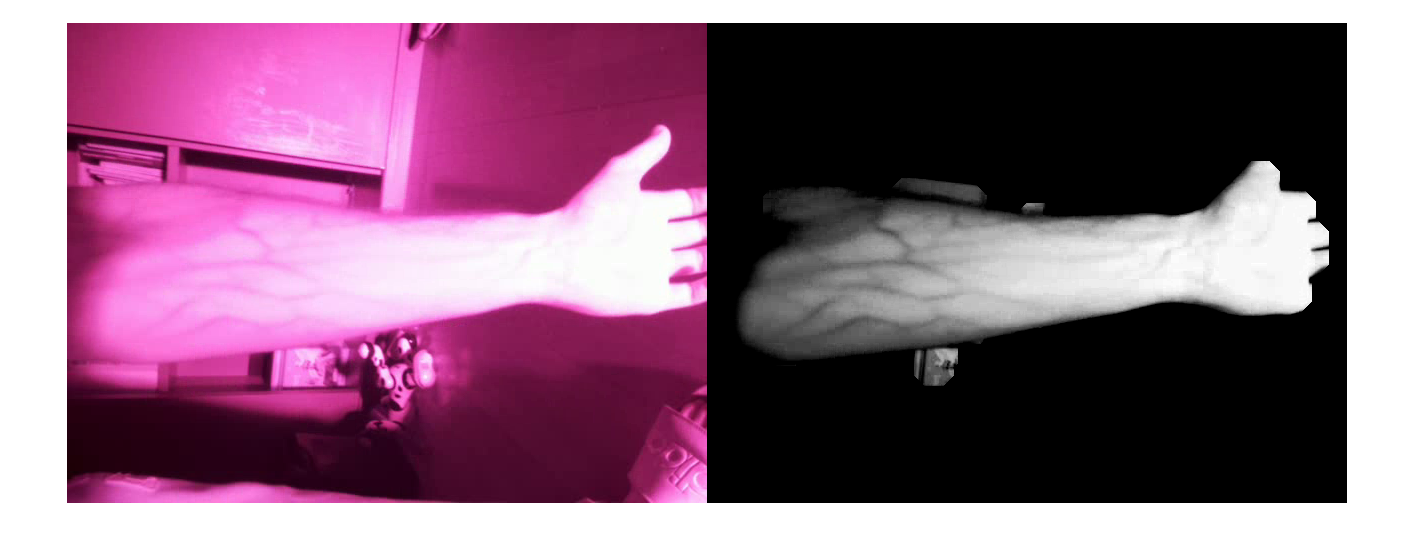

for i = 1:numel(images)
%     resized = imresize(images{i}, resize);
    name = strrep(baseName{i}, '.png', '');
%     figure, title(name,'FontSize',22,'Interpreter','none'), hold on
    imshowpair(images{i}, prcd_ims{i}, 'montage');
end

## Line Detection

#### Basic Algorithm

line_array = cell(size(prcd_ims));

for i = 1:numel(prcd_ims)
    im = prcd_ims{i};
    
    switch lower(method)
        case 'sobel'
            lines = edge(im,'sobel');
        case 'prewitt'
            lines = edge(im,'prewitt');
        case 'roberts'
            lines = edge(im,'roberts');
        case 'log'
            lines = edge(im,'log');
        case 'zerocross'
            lines = edge(im,'zerocross');
        case 'canny'
            lines = edge(im,'canny');
%             lines = edge(im,'canny',[0.015 0.025]);
        case 'approxcanny'
            lines = edge(im,'approxcanny');
        otherwise
            throw("Invalid line detection method given.")
    end
    
    line_array{i} = lines;
end

#### Visualize

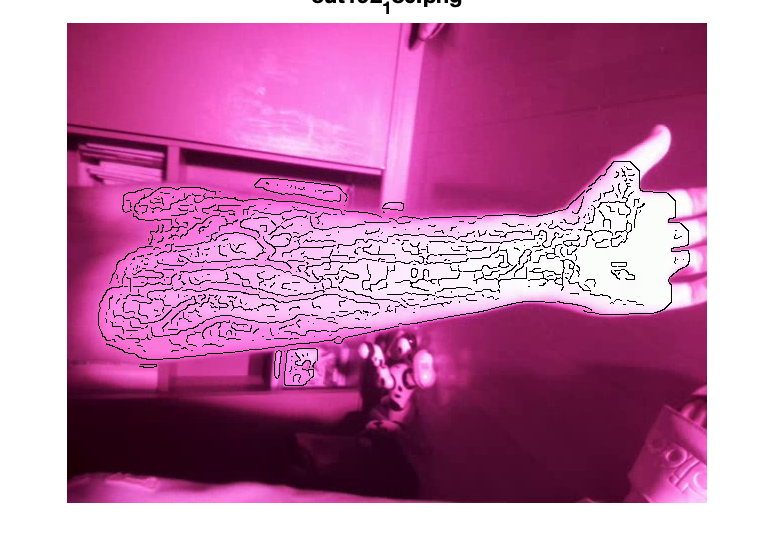

for i = 1:numel(images)
%     im = imresize(images{i}, resize);
    overlay = imoverlay(images{i}, line_array{i}, 'black');
    figure, imshow(overlay);
    title(baseName{i},'FontSize',22)
end

#### Postprocessing

line_array_pp = line_array;

min_len = 10;
max_len = 500;
pp_dil_size = 9;
pp_range = deg2rad(15);
pp_sigma = 4;
pp_thresh = 0.7;
pp_smooth = 1.2;
conv_thresh = 125 / 255;

for k = 1:numel(images)
    
    % Remove short & long lines
%     CC = bwconncomp(line_array_pp{k});
%     S = regionprops(CC, 'Area');
%     L = labelmatrix(CC);
%     Range = find(([S.Area]>min_len)&([S.Area]<max_len));
%     lines = ismember(L, Range);

    lines = bwareaopen(line_array_pp{k}, min_len);

    % Compare
%     imshowpair(lines, line_array{k}, 'montage')
%     title('Remove Short & Long Lines', 'FontSize', 22)
    
    % Dilate along lines
    shift = (90 / (pp_dil_size-1));
    fin_lines = zeros(size(lines));
    for deg = 0:shift:180-shift
        
        % Create structing element
        se1 = customStrel(pp_dil_size, pp_range, pp_sigma, deg);

        % Erode to detect lines
        st_lines = conv2(lines,se1,'same');
        
        % Thresholding
        th_lines = (st_lines > conv_thresh);
        
        % Dilate along lines
%         se2 = customStrel(15, 0, 1.8, deg);
%         dil_lines = conv2(th_lines,se2,'same');
        
        % Add
        fin_lines = fin_lines + th_lines;
    end

    % Convert to BW
    lines = fin_lines > pp_thresh;
    
    % Remove short lines
    lines = bwareaopen(lines, 25);

    line_array_pp{k} = lines;
end

#### Visualize

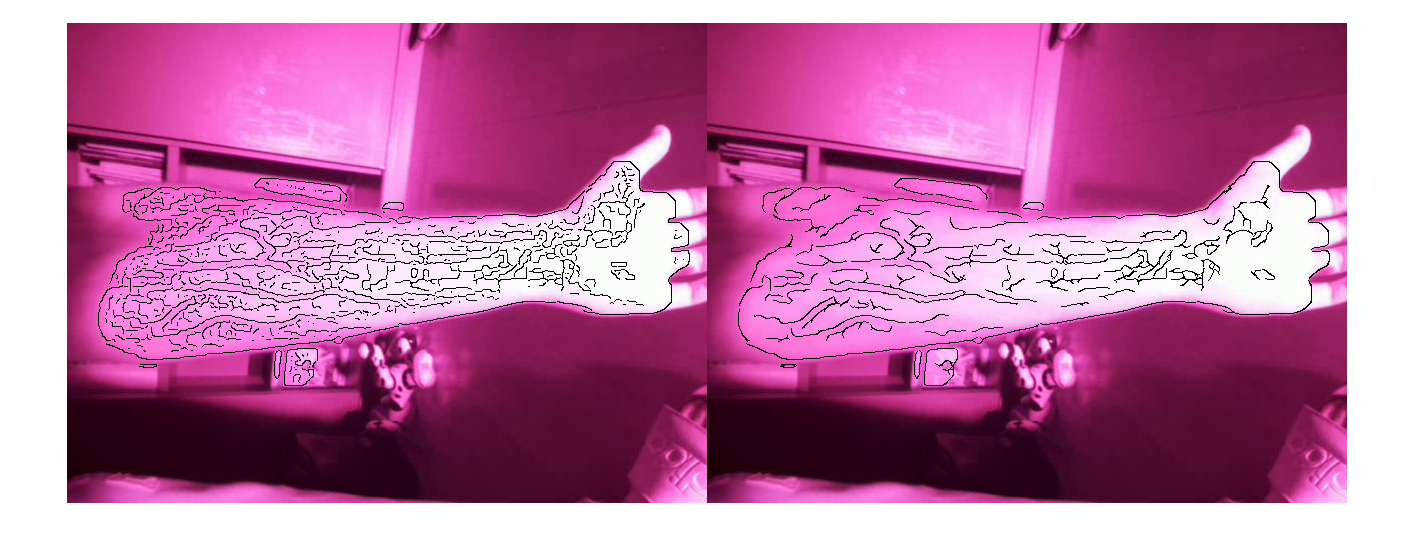

for i = 1:numel(images)
%     im = imresize(images{i}, resize);
    overlay1 = imoverlay(images{i}, line_array{i}, 'black');
    overlay2 = imoverlay(images{i}, line_array_pp{i}, 'black');
    figure, imshowpair(overlay1, overlay2, 'montage');
%     title(baseName{i},'FontSize',22)
end

## Vein Selection

vein_array = line_array;
% vein_array = line_array_pp;

vein_len = 9;
vein_width = 4;
vein_sigma = 0.5;
vein_thresh = 90 / 255;

shift = (60/(vein_len-1));

% vid = {};

for k = 1:numel(images)
    
    lines = vein_array{k};
%     lines = imgaussfilt(255*lines, vein_sigma);
    
    % Convolution
    veins = false(size(lines));
    for deg = 0:shift:180-shift
        
        th_veins = zeros(size(veins));
        
        for i = vein_width:vein_width+2
        
            % Create structing element
            se1 = customStrel2(vein_len, i, vein_sigma, deg, 'center');
           
            % Convolution to detect veins
            st_veins = conv2(lines,se1,'same');
           
            % Thresholding
            th_veins = (st_veins > vein_thresh);
    %         vid{end+1} = imoverlay(lines,(st_veins>vein_thresh),'red');
            
            % Dilate along veins
            se2 = strel('line', 8, deg);
            dil_veins = conv2(th_veins,se2.Neighborhood,'same');
            
            % Remove short lines
            dil_veins = bwareaopen(dil_veins, 12);
            
            % Add
            veins(dil_veins>0) = 1;    
           
        end
        
%         vid{end+1} = imshow(imoverlay(lines, veins,'red'));
%         figure, imshow(imoverlay(lines, veins,'red'))
    end
    
    
    % Remove short lines
    veins = imclose(veins, strel('disk',1));
    veins = bwareaopen(veins, 45);
    
    vein_array{k} = veins;
end

#### Visualize

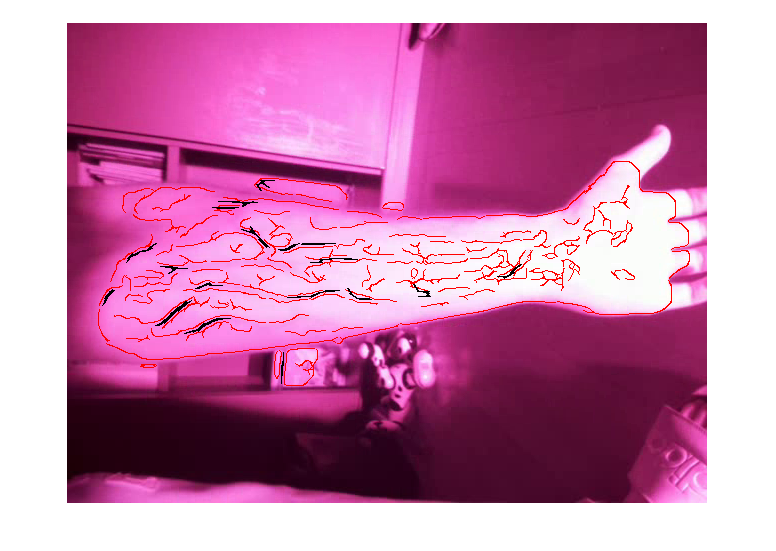

for i = 1:numel(images)
%     im = imresize(images{i}, resize);
    overlay1 = imoverlay(images{i}, line_array_pp{i}, 'red');
    overlay2 = imoverlay(overlay1, vein_array{i}, 'black');
%     figure, title(baseName{i},'FontSize',22)
%     imshowpair(overlay1,overlay2,'montage');
    imshow(overlay2)
end

## Vein Detection w/o Lines

## Visualize

% % Visualize
% fig1 = figure;
% imshow(im_crop), title('Gray, Cropped'), hold on
% imwrite(im_crop, strcat("output/", string(ids(1)), "gray.png"), 'png')

% fig2 = figure;
% imshow(overlay), title('Roberts lines'), hold on
% imwrite(overlay, strcat("output/", string(ids(1)), "roberts.png"), 'png')

% fig3 = figure;
% imshow(im_veins), title('Vein Detection'), hold on
% imwrite(im_veins, strcat("output/", string(ids(1)), "veins.png"), 'png')

## Convert Video to Images

% % % Convert to images
% vid = read('vid.mpa'); % load video
% for i = 1:size(vid, 4)
%     frame = vid(:,:,:,i); 
%     imwrite(frame, strcat(string(i), ".png"), 'png')
% end